### `Laura Sofia Ortiz `

# `TALLER 3`

#### `En un teléfono de tonos, hay una frecuencia asociada con cada columna y cada fila del teclado. Cuando se presiona un botón, la señal transmitida por la linea telefonica es la suma de dos sinusoides, una con la frecuencia de columna y otra con la frecuencia de fila.`

#### `Este sistema se denomina DTMF. Vamos a tener que las frecuencias de las columnas son: 1209, 1306 y 1477 Hz de izquierda a derecha, con 1633 Hz asociados con una cuarta columna que generalmente no esa. Las frecuenciasde fila son: 697, 770, 852 y 941 Hz, de arriba a abajo. Cada tono debe tener una duración de al menos 40mseg y el espacio entre tonos de 40mseg.`

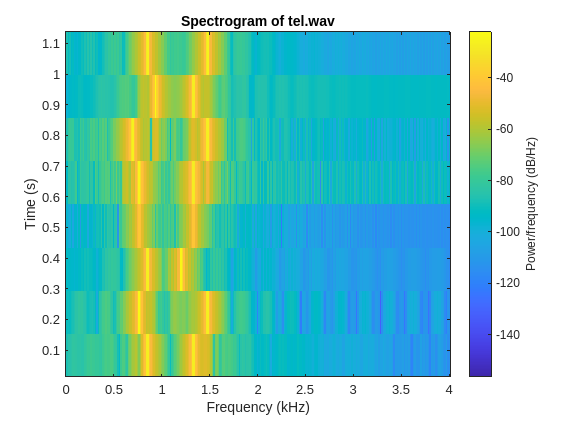

clc;

% Cargar la señal de audio
[y, Fs] = audioread('tel.wav');

% Calcular la Transformada de Fourier de la señal
Y = fft(y);

% Definir el vector de frecuencia correspondiente a la Transformada de Fourier
f = linspace(-Fs/2, Fs/2, length(Y));

% Graficar el espectrograma, esto lo hacemos para ver las frecuencias
% asociadas con la columna y la fila, para asi decodificar el numero

winlen = round(Fs*0.04);     % Longitud de la ventana 
overlap = 200;               % Superposición entre ventanas
nfft = 2^nextpow2(winlen);   % Longitud de la transformada de Fourier

spectrogram(y, [], overlap, nfft, Fs);
title("Spectrogram of tel.wav")

#### `El espectrograma nos ayuda a visualizar cómo la energía de la señal se distribuye en el tiempo y en la frecuencia. En el caso de la señal de marcación telefónica, el espectrograma nos muestra las regiones de energía en las frecuencias correspondientes a los tonos DTMF que se utilizaron para marcar el número. Esto puede ayudarnos a identificar los tonos, lo que a su vez puede ser utilizado para decodificar el número marcado.`

#### `Así, el espectrograma nos proporciona información visual que nos ayuda a identificar patrones en la señal, lo que puede ser útil en la decodificación de la señal.`

#### `Teniendo en cuenta el espectrograma, y que las frecuencias tenemos que verlas de izquierda a derecha, y de arriba a abajo como se indica arriba, podemos ver que el espectrograma nos muestra 7 numeros decodificados. Analizando la grafica donde estan las lineas, y el teclado del telefono con sus respectivas frecuencias, los numeros son:`

- `El primer tono genera el numero 9.`

- `El segundo genera el numero 0.`

- `El tercero el numero 3.`

- `El cuarto el numero 5.`

- `El quinto el numero 7.`

- `El sexto el numero 6.`

- `Y el ultimo tono el numero 8.`

#### `Por lo tanto el numero marcado fue 9035768.`